# **FILTRAGEM ADAPTATIVA**

# **TRABALHO AP2**

Autor: Rômulo Bandeira Pimentel Drumond

Para as simulações de equalização do canal foram escolhidos como hiper-parâmetros, além dos expostos no enunciado da questão:

- Número de símbolos processados = 10.000;

- *Seed* do gerador de número aleatórios = 2018 (visa reprodutibilidade das simulações).

close all
clear all
clc

% Parâmetros
ns = 1e4;    % Total de símbolos a serem processados 
C = 4;       % Tamanho da constelacao C-QAM
snr = 10*log10(20); % Signal-to-noise ratio em dB = 13dB
k = log2(C);    % k bits por simbolo. 

% Gera o vetor de ns símbolos (ns*k bits) aleatorios
rng(2018); % fixa a semente do gerador de numeros aleatorios
data = randi([0 1],ns*k,1);

% Modula C-QAM
d = qammod(data,C, 'InputType','bit');%,'PlotConstellation',true);

% Constelação sem ruído
%cd1 = comm.ConstellationDiagram('ShowReferenceConstellation',false); step(cd1,d);
% Constelação com ruído
%cd2 = comm.ConstellationDiagram('ShowReferenceConstellation',false); step(cd2,awgn(d,snr));

## Transmite por um canal com interferencia inter-simbolica e ruido branco 

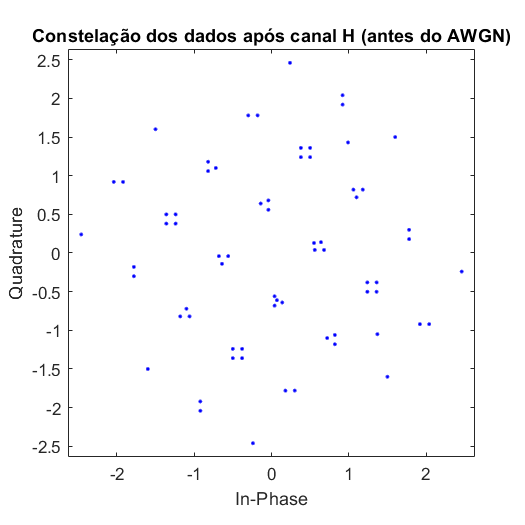

h = [0.34 - 0.21j; 0.87 + 0.43j; 0.34 - 0.27j];
X = conv(d,h); % Neste ponto X contem o sinal recebido atraves do canal

% Plota a constelação de X
scatterplot(X); title("Constelação dos dados após canal H (antes do AWGN)");

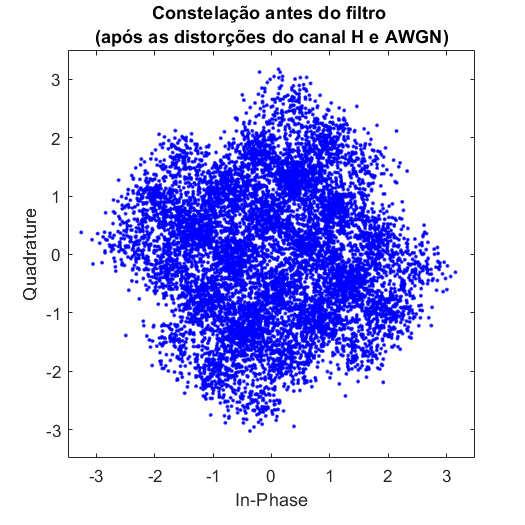

% Acrescenta ruido AWGN a X
rng(2018);
X = awgn(X,snr,'measured'); 
 
% Plota a constelação de X com ruído
scatterplot(X);
title(sprintf("Constelação antes do filtro \n(após as distorções do canal H e AWGN)"));

## Aplicação do RLS

Para a escolha do hiper-parâmetro $\lambda$ foi realizada uma busca em grade entre os valores 0.95 e 0.99. Como métricas de avaliação foram utilizadas:

- *Symbol Error Rate* (SER);

- *Bit Error Rate* (BER);

- Média do Módulo do Erro (MME). 

Funções auxiliares foram criadas para tornar o código mais legível:

% Parâmetros do RLS:
n_coef = 10;
delta = 1e-2;
lambdas = linspace(0.95, 0.99, 100);

% Aplicação do RLS e avaliação para cada valor de lambda:
tic
SER=zeros(size(lambdas)); BER=zeros(size(lambdas)); MME=zeros(size(lambdas));
for i=1:length(lambdas)
    [Y, w, e]= RLS(d,X,n_coef,lambdas(i),delta);
    [SER(i), BER(i), MME(i)] = evalMetrics(d,Y,e,C);
end
toc

Elapsed time is 287.731548 seconds.


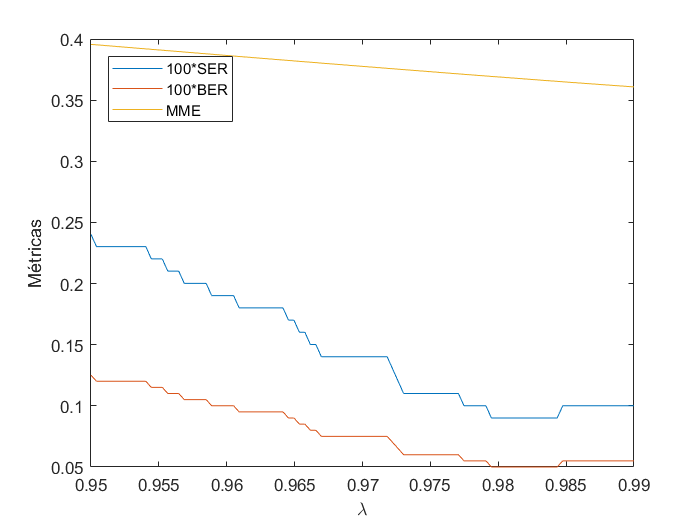

figure; plot(lambdas,1e2*SER); hold on; plot(lambdas, 1e2*BER); plot(lambdas,MME); legend('100*SER','100*BER','MME');
xlim([0.95 0.99]); xlabel('\lambda'); ylabel('Métricas'); legend('Location','northwest');

[minSER, iSER] = min(SER);
[minBER, iBER] = min(BER);
[minMME, iMME] = min(MME);
fprintf(...
    'SER_{minimum} = %e => lambda = %.6f\nBER_{minimum} = %e => lambda = %.6f\nMME_{minimum} = %e => lambda = %.6f', ...
    minSER, lambdas(iSER), minBER, lambdas(iBER), minMME, lambdas(iMME))

SER_{minimum} = 9.008107e-04 => lambda = 0.979495
BER_{minimum} = 5.004504e-04 => lambda = 0.979495
MME_{minimum} = 3.608388e-01 => lambda = 0.990000

Como as três métricas divergem entre si foi escolhido arbitrariamente o valor que minimiza o SER como lambda ótimo:

lambda_opt = lambdas(iSER)

lambda_opt = 0.9795

n_coef = 10;
[Y_10, w_10, e_10]= RLS(d,X,n_coef,lambda_opt,delta);
[SER_10, BER_10, MME_10] = evalMetrics(d,Y_10,e_10,C);

fprintf('Valor das três métricas quando len(w)=%d: \nSER = %e\nBER = %e\nMME = %e', ...
         n_coef, SER_10, BER_10, MME_10);

Valor das três métricas quando len(w)=10: 
SER = 9.008107e-04
BER = 5.004504e-04
MME = 3.694145e-01

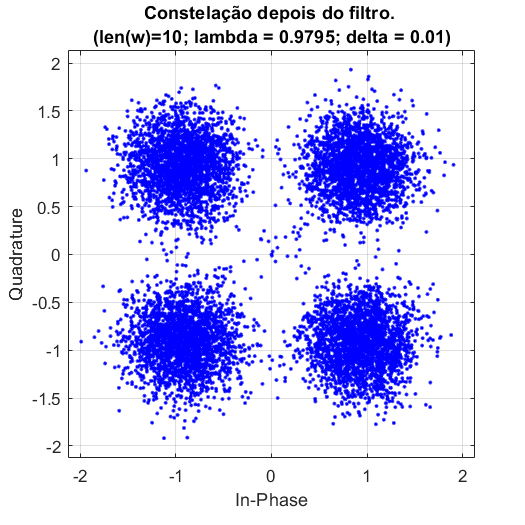

% Plota a constelação de Y
scatterplot(Y_10);
name = sprintf("Constelação depois do filtro. \n(len(w)=%d; lambda = %.4f; delta = %.2f)", 10, lambda_opt, delta);
title(name); grid on;

O gráfico abaixo foi gerado para analisarmos o comportamento de convergência do algoritmo.

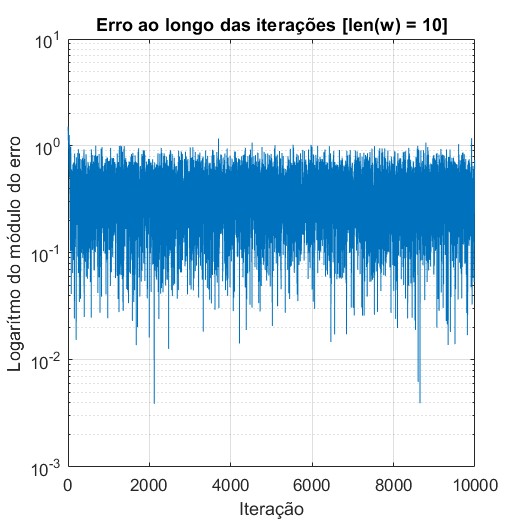

semilogy(abs(e_10));
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title('Erro ao longo das iterações [len(w) = 10]'); grid on;

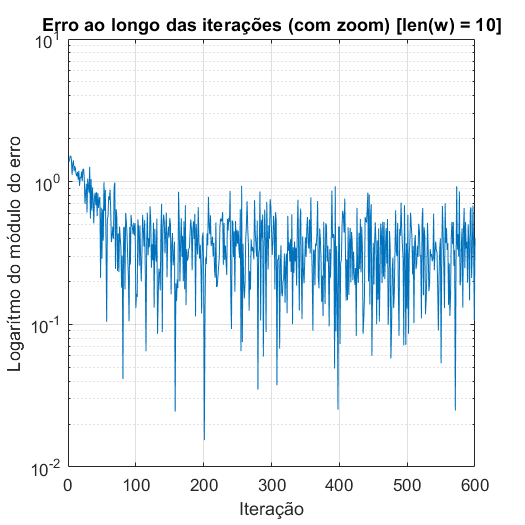

semilogy(abs(e_10));
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title('Erro ao longo das iterações (com zoom) [len(w) = 10]'); grid on; xlim([0 600]);

Podemos ver que após aproximadamente 100 iterações o algoritmo converge, restando a oscilação natural do desajuste dos valores do filtro ótimo.

Posteriormente **o número de coeficientes do filtro foi aumentado para 20**, mantendo constante os outros hiper-parâmetros:

n_coef = 20;
[Y_20, w_20, e_20]= RLS(d,X,n_coef,lambda_opt,delta);
[SER_20, BER_20, MME_20] = evalMetrics(d,Y_20,e_20,C);

fprintf('Valor das três métricas quando len(w)=%d: \nSER = %f\nBER = %f\nMME = %f', ...
         20, SER_20, BER_20, MME_20);

Valor das três métricas quando len(w)=20: 
SER = 0.002605
BER = 0.001403
MME = 0.387526

fprintf('Valor das três métricas quando len(w)=%d: \nSER = %f\nBER = %f\nMME = %f', ...
         10, SER_10, BER_10, MME_10);

Valor das três métricas quando len(w)=10: 
SER = 0.000901
BER = 0.000500
MME = 0.369415

Pelas três métrica utilizadas para escolher o valor de lambda, pode-se dizer que **o filtro teve um desempenho pior quando seu número de coeficientes aumentou para 20**.

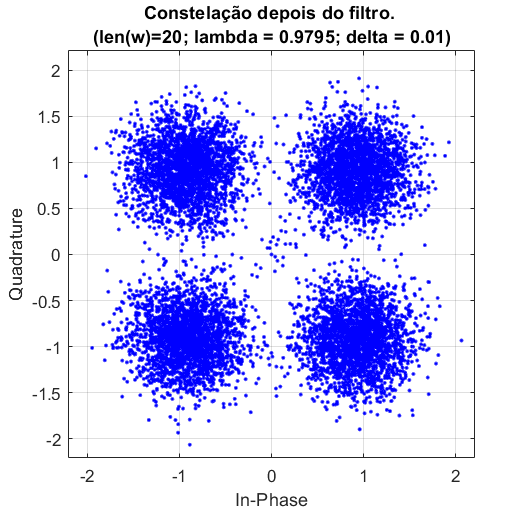

% Plota a constelação de Y
scatterplot(Y_20);
name = sprintf("Constelação depois do filtro. \n(len(w)=%d; lambda = %.4f; delta = %.2f)", n_coef, lambda_opt, delta);
title(name); grid on;

Comparando as constelações após o filtro ser aplicado para os casos que len(w) = 10 e len(w) = 20 também podemos perceber que para o filtro com maior coeficientes há uma dispersão levemente maior dos dados.

Novamente foi contruído o gráfico do módulo do erro ao longo das iterações:

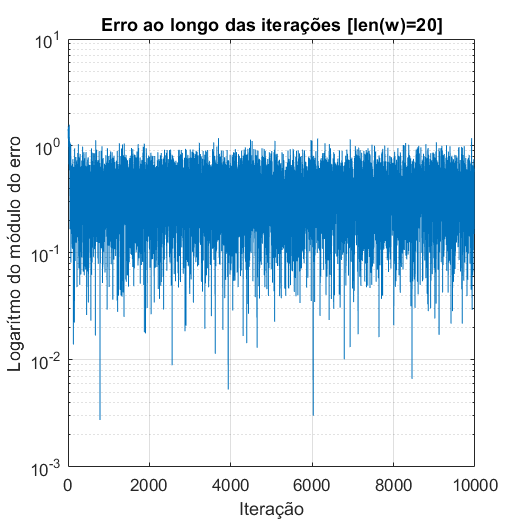

semilogy(abs(e_20));
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title('Erro ao longo das iterações [len(w)=20]'); grid on;

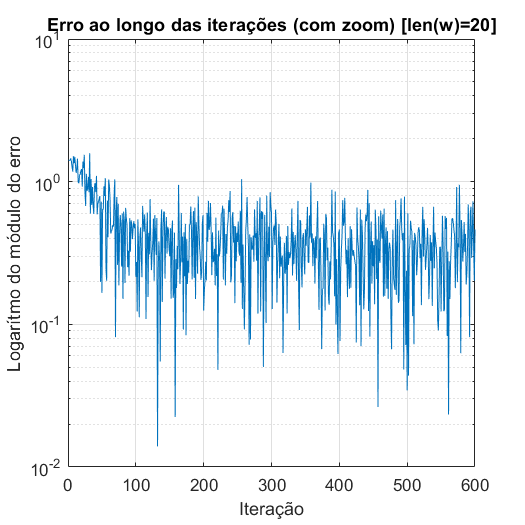


semilogy(abs(e_20));
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title('Erro ao longo das iterações (com zoom) [len(w)=20]'); grid on; xlim([0 600]);

Percebe-se que os gráficos do erro para len(w)=10 e len(w)=20 não diferem muito.

Para título de curiosidade foi estudado o efeito do número de coeficientes do filtro nas três métricas utilzadas nesse trabalho (SER, BER MME):

% Parâmetros:
n_coefs = 2:100; % de 2 a 100 coeficientes
% Aplicação do RLS e avaliação das métricas para cada valor de n_coef:
tic
SER=zeros(size(n_coefs)); BER=zeros(size(n_coefs)); MME=zeros(size(n_coefs));
for i=1:length(n_coefs)
    [Y, w, e]= RLS(d,X,n_coefs(i),lambda_opt,delta);
    [SER(i), BER(i), MME(i)] = evalMetrics(d,Y,e,C);
end
toc

Elapsed time is 846.398283 seconds.


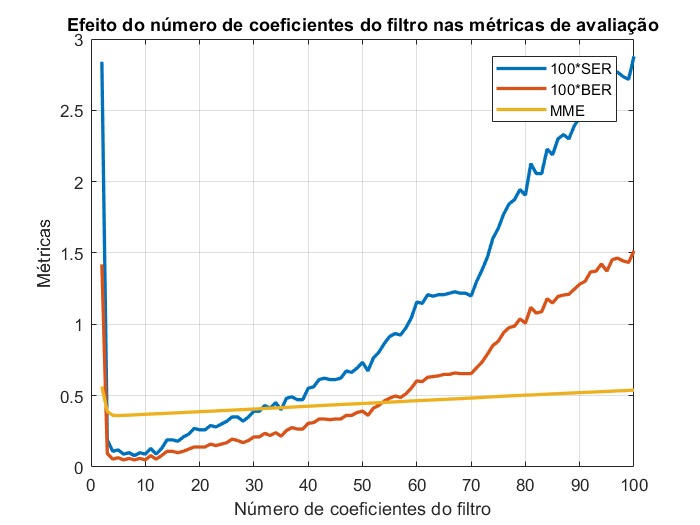

figure; plot(n_coefs,1e2*SER,'LineWidth',2); hold on; %xlim([n_coefs(1) n_coefs(end)]);
plot(n_coefs, 1e2*BER,'LineWidth',2); plot(n_coefs,MME,'LineWidth',2); legend('100*SER','100*BER','MME');
xlabel('Número de coeficientes do filtro'); ylabel('Métricas'); grid on;
title('Efeito do número de coeficientes do filtro nas métricas de avaliação')

Podemos ver que há uma tendência para que a performance do filtro piore na faixa estudada de 10 a 20 coeficientes, sendo os valores ótimos de acordo com cada métrica:

[minSER, iSER] = min(SER);
[minBER, iBER] = min(BER);
[minMME, iMME] = min(MME);
fprintf(...
    'SER_{minimum} = %e => n_coef = %d\nBER_{minimum} = %e => n_coef = %d\nMME_{minimum} = %e => n_coef = %d', ...
    minSER, n_coefs(iSER), minBER, n_coefs(iBER), minMME, n_coefs(iMME))

SER_{minimum} = 8.005604e-04 => n_coef = 8
BER_{minimum} = 5.002501e-04 => n_coef = 6
MME_{minimum} = 3.603195e-01 => n_coef = 5

Foram feitos gráficos para as saídas do filtro no caso em que n_coef=8 e n_coef=100:

[Y_SER,  ~,~] = RLS(d,X,n_coefs(iSER),lambda_opt,delta);
[Y_nMax, ~,~] = RLS(d,X,n_coefs(end),lambda_opt,delta);

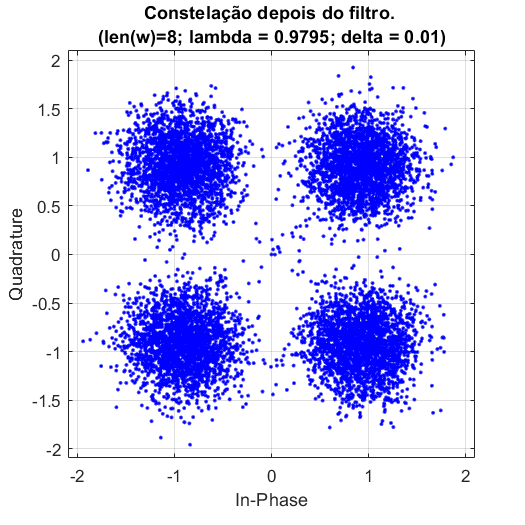

% Plota as constelações
% n_coef = n_coefs(iSER)
scatterplot(Y_SER);
name = sprintf("Constelação depois do filtro. \n(len(w)=%d; lambda = %.4f; delta = %.2f)", n_coefs(iSER), lambda_opt, delta);
title(name); grid on;

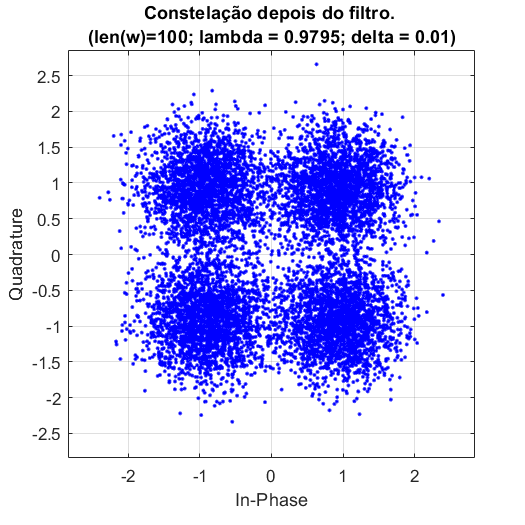


% n_coef = n_coefs(end)
scatterplot(Y_nMax);
name = sprintf("Constelação depois do filtro. \n(len(w)=%d; lambda = %.4f; delta = %.2f)", ...
    n_coefs(end), lambda_opt, delta);
title(name); grid on;

Agora ficou mais clara a dispersão maior, ou queda de performance, ocasionada pelo aumento do número de coeficientes do filtro.

## QUESTÃO 02 - ITL

Para essa questão foi utilizado o Error Correntropy Criterion (ECC), com kernel gaussiano e janela de um dado para a função custo:


$$J(n)=\frac{1}{\sqrt{2\pi}\sigma}e^{-(d(n)-y(n))^2/2\sigma^2}}$$


Onde y(n) é a saída do filtro no instante n.

Portanto temos como regra de atualização:


$$w(n+1) = w(n) + \frac{\eta}{\sqrt{2\pi}\sigma^3}e^{-e(n)^2/2\sigma^2}e(n)x(n)$$


Onde e(n) é o erro na iteração n: $e(n) = d(n)-y(n)$

Uma função auxiliar foi criada para aplicar o gradiente ascendente com EEC. Para escolhermos o falor de eta foi realizada uma busca em grade pelo hiper-parâmetro, de forma similar à busca pelo valor de lambda no RLS .

% Hiper-parâmetros
etas = linspace(2.75e-2,1e-5,100);
n_coef = 10;
sigma = 1;

% Aplicação do daECC e avaliação para cada valor de eta:
tic
SER_ITL=zeros(size(etas)); BER_ITL=zeros(size(etas)); MME_ITL=zeros(size(etas));
for i=1:length(etas)
    [Y, ~, e] = gaEEC(d,X,n_coef,etas(i),sigma);
    [SER_ITL(i), BER_ITL(i), MME_ITL(i)] = evalMetrics(d,Y,e,C);
end
toc

Elapsed time is 439.741252 seconds.


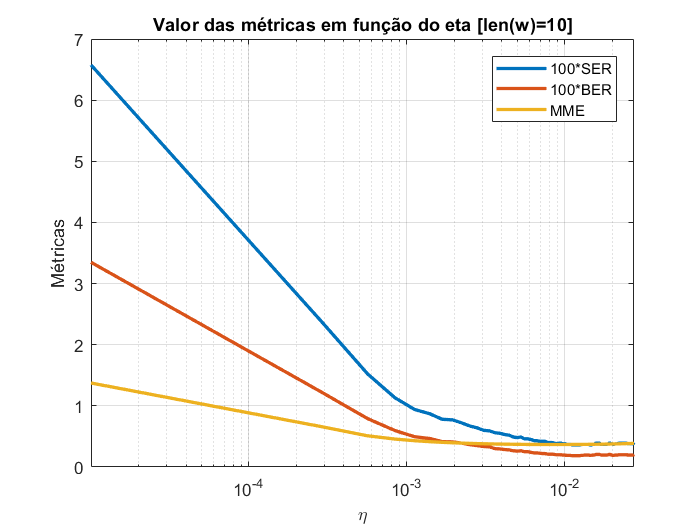

figure; semilogx(etas,1e2*SER_ITL,'LineWidth',2); hold on; semilogx(etas, 1e2*BER_ITL,'LineWidth',2); 
semilogx(etas,MME_ITL,'LineWidth',2); legend('100*SER','100*BER','MME'); grid on; xlim([etas(end) etas(1)]);
xlabel('\eta'); ylabel('Métricas');
title('Valor das métricas em função do eta [len(w)=10]')


[minSER_ITL, iSER_ITL] = min(SER_ITL);
[minBER_ITL, iBER_ITL] = min(BER_ITL);
[minMME_ITL, iMME_ITL] = min(MME_ITL);
fprintf(...
    ['SER_ITL{minimum} = %e => eta = %.4e\n' ...
     'BER_ITL{minimum} = %e => eta = %.4e\n' ...
     'MME_ITL{minimum} = %e => eta = %.4e'], ...
    minSER_ITL, etas(iSER_ITL), minBER_ITL, etas(iBER_ITL), minMME_ITL, etas(iMME_ITL))

SER_ITL{minimum} = 3.603243e-03 => eta = 1.4727e-02
BER_ITL{minimum} = 1.851666e-03 => eta = 1.2505e-02
MME_ITL{minimum} = 3.677712e-01 => eta = 8.6180e-03

Foi escolhido seguir a métrica SER para determinar o eta ótimo:

eta_opt = etas(iSER_ITL)

eta_opt = 0.0147

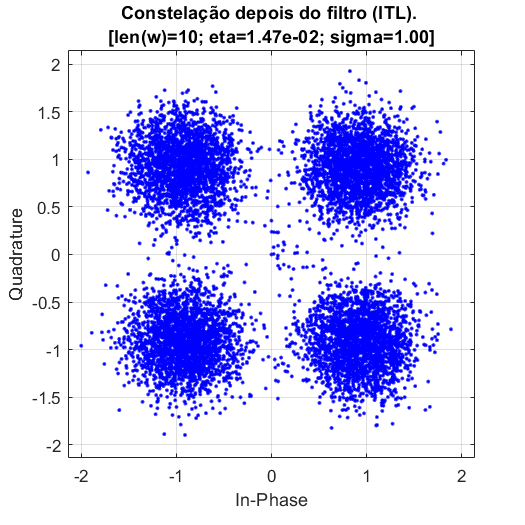

[Y, ~, e] = gaEEC(d,X,n_coef,eta_opt,sigma);
figure; scatterplot(Y);
name = sprintf("Constelação depois do filtro (ITL). \n[len(w)=%d; eta=%.2e; sigma=%.2f]", ...
    n_coef, eta_opt, sigma);
title(name); grid on;

Foram feitos gráficos do módulo do erro ao longo das iterações:

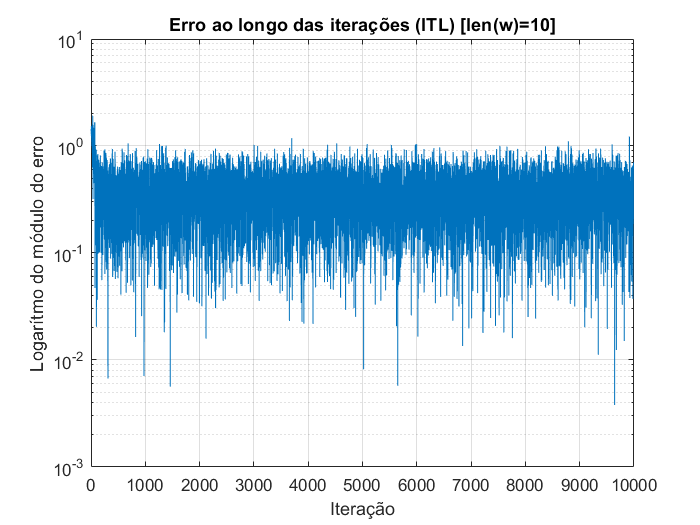

figure; semilogy(abs(e)); 
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title(sprintf('Erro ao longo das iterações (ITL) [len(w)=%d]', n_coef)); grid on;

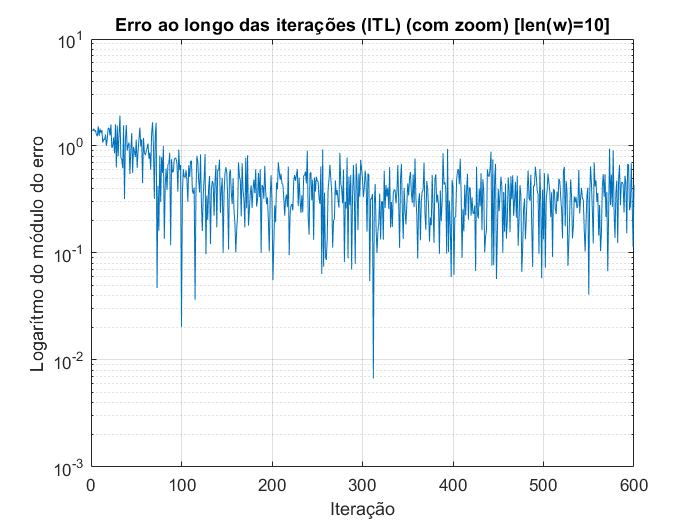

figure; semilogy(abs(e)); xlim([0 600]);
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title(sprintf('Erro ao longo das iterações (ITL) (com zoom) [len(w)=%d]', n_coef)); grid on;


[SER_ITL, BER_ITL, MME_ITL] = evalMetrics(d,Y,e,C);

fprintf('Valor das três métricas quando len(w)=%d: \nSER = %f\nBER = %f\nMME = %f', ...
         n_coef, SER_ITL, BER_ITL, MME_ITL);

Valor das três métricas quando len(w)=10: 
SER = 0.003603
BER = 0.001902
MME = 0.370957

Podemos ver no gráfico com zoom que o algoritmo converge em torno de 200 iterações, depois disso ocorrer as oscilações naturais do gradiente ascendente.

**Posteriormente a análise foi repetida para o caso em que o número de coeficientes do filtro era 20.**

Durante as simulações um problema foi encontrado: o algoritmo tinha problemas para convergir quando utilizado o eta_opt do caso de len(w)=10, portanto foi realizada novamente uma busca pelo hiper-parâmetro eta:

etas = linspace(1e-2,1e-5,100);
n_coef = 20;
sigma = 1;

% Aplicação do daECC e avaliação para cada valor de eta:
tic
SER_ITL=zeros(size(etas)); BER_ITL=zeros(size(etas)); MME_ITL=zeros(size(etas));
for i=1:length(etas)
    [Y, ~, e] = gaEEC(d,X,n_coef,etas(i),sigma);
    [SER_ITL(i), BER_ITL(i), MME_ITL(i)] = evalMetrics(d,Y,e,C);
end
toc

Elapsed time is 440.568034 seconds.


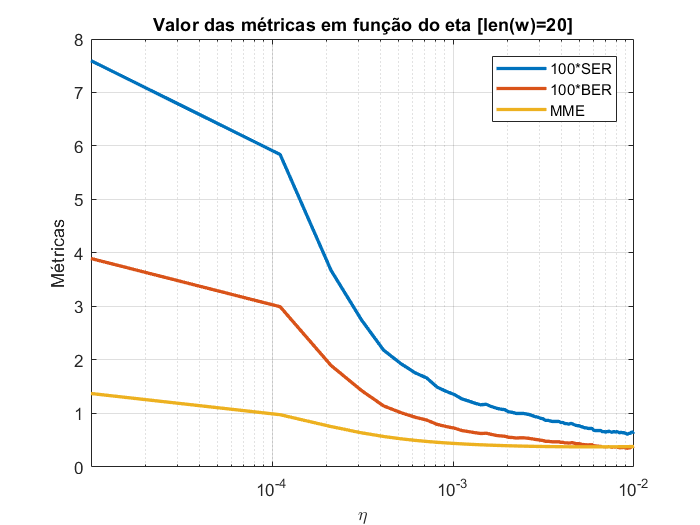


figure; semilogx(etas,1e2*SER_ITL,'LineWidth',2); hold on; semilogx(etas, 1e2*BER_ITL,'LineWidth',2); 
semilogx(etas,MME_ITL,'LineWidth',2); legend('100*SER','100*BER','MME'); grid on; xlim([etas(end) etas(1)]);
xlabel('\eta'); ylabel('Métricas'); %legend('Location','northwest');
title(sprintf('Valor das métricas em função do eta [len(w)=%d]', n_coef))


[minSER_ITL, iSER_ITL] = min(SER_ITL);
[minBER_ITL, iBER_ITL] = min(BER_ITL);
[minMME_ITL, iMME_ITL] = min(MME_ITL);
fprintf(...
    ['SER_ITL{minimum} = %e => eta = %.4e\n' ...
     'BER_ITL{minimum} = %e => eta = %.4e\n' ...
     'MME_ITL{minimum} = %e => eta = %.4e'], ...
    minSER_ITL, etas(iSER_ITL), minBER_ITL, etas(iBER_ITL), minMME_ITL, etas(iMME_ITL))

SER_ITL{minimum} = 6.111612e-03 => eta = 9.1927e-03
BER_ITL{minimum} = 3.506663e-03 => eta = 9.1927e-03
MME_ITL{minimum} = 3.768924e-01 => eta = 5.7618e-03

eta_opt = etas(iSER_ITL)

eta_opt = 0.0092

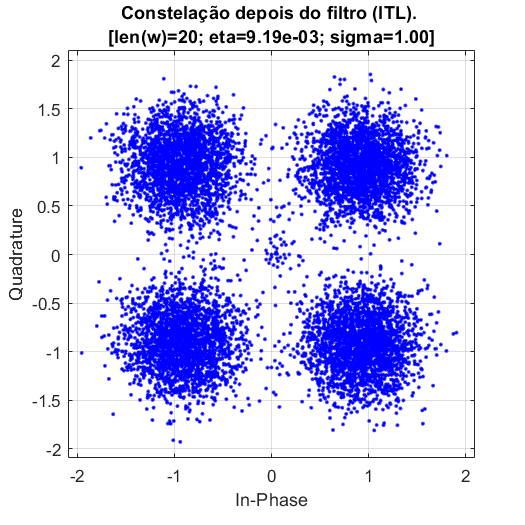

[Y_ITL_20, ~, e_ITL_20] = gaEEC(d,X,20,eta_opt,sigma);
figure; scatterplot(Y_ITL_20);
name = sprintf("Constelação depois do filtro (ITL). \n[len(w)=%d; eta=%.2e; sigma=%.2f]", ...
    20, eta_opt, sigma);
title(name); grid on;

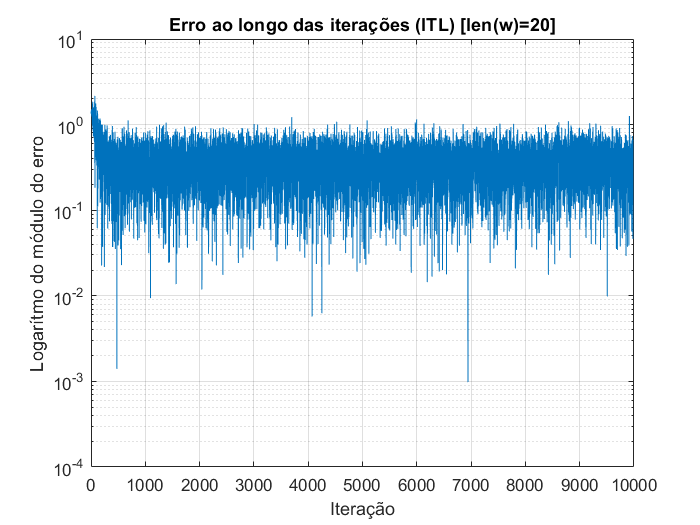


figure; semilogy(abs(e_ITL_20)); 
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title(sprintf('Erro ao longo das iterações (ITL) [len(w)=%d]', n_coef)); grid on;

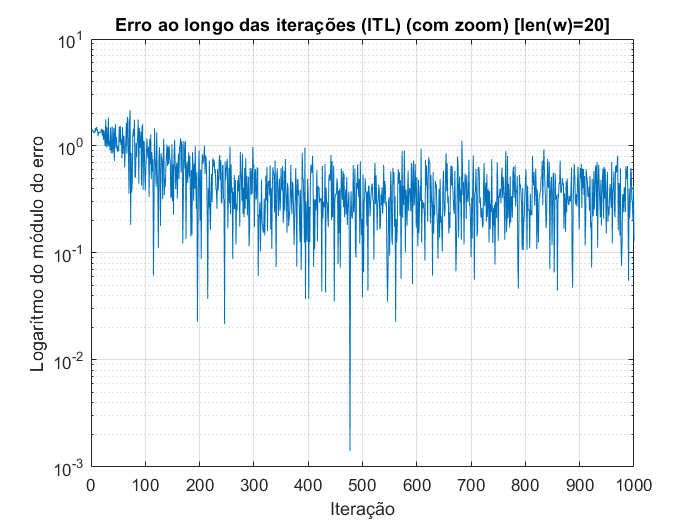

figure; semilogy(abs(e_ITL_20)); xlim([0 1000]);
xlabel('Iteração'), ylabel('Logarítmo do módulo do erro')
title(sprintf('Erro ao longo das iterações (ITL) (com zoom) [len(w)=%d]', n_coef)); grid on;


[SER_ITL_20, BER_ITL_20, MME_ITL_20] = evalMetrics(d,Y_ITL_20,e_ITL_20,C);

fprintf('Valor das três métricas quando len(w)=%d: \nSER = %f\nBER = %f\nMME = %f', ...
         20, SER_ITL_20, BER_ITL_20, MME_ITL_20);

Valor das três métricas quando len(w)=20: 
SER = 0.006112
BER = 0.003507
MME = 0.380757

De forma geral o filtro com 10 coeficientes teve um desempenho superior segundo as 3 métricas utilizadas. Em termos de convergência o filtro com 20 coeficientes precisou aproximadamente de 400 iterações, número maior que o filtro com 10 coeficientes por causa do eta menor. A constelação do filtro de 20 também apresenta mais pontos no centro, que devem ser ocasionados pelo fator de passo menor (eta), que leva o algoritmo precisar de mais iterações para conseguir equalizar o canal.

## Análise do efeito do número de coeficientes nas métricas de performance para o gaEEC

De forma semelhante ao caso do RLS variamos o número de coeficientes do filtro para ver seu impacto nas métricas de avaliação. Para tal simulação foi escolhido um valor de eta que levasse à convergência os filtros de 2 a 100 coeficientes.

% Parâmetros:
eta = 2.5e-3;
n_coefs = 100:-1:2; % de 2 a 100 coeficientes
% Aplicação do gaEEC e avaliação das métricas para cada valor de n_coef:
tic
SER=zeros(size(n_coefs)); BER=zeros(size(n_coefs)); MME=zeros(size(n_coefs));
for i=1:length(n_coefs)
    [Y, ~, e]= gaEEC(d,X,n_coefs(i),eta,sigma);
    [SER(i), BER(i), MME(i)] = evalMetrics(d,Y,e,C);
    %sprintf('%d',n_coefs(i))
end
toc

Elapsed time is 402.165229 seconds.


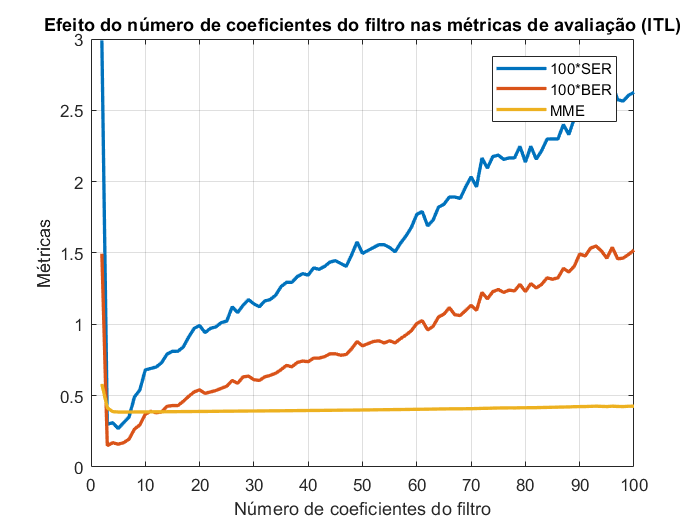

figure; plot(n_coefs,1e2*SER,'LineWidth',2); hold on; %xlim([n_coefs(1) n_coefs(end)]);
plot(n_coefs, 1e2*BER,'LineWidth',2); plot(n_coefs,MME,'LineWidth',2); legend('100*SER','100*BER','MME');
xlabel('Número de coeficientes do filtro'); ylabel('Métricas'); grid on;
title('Efeito do número de coeficientes do filtro nas métricas de avaliação (ITL)')


[minSER, iSER] = min(SER);
[minBER, iBER] = min(BER);
[minMME, iMME] = min(MME);
fprintf(...
    ['SER_(ITL){minimum} = %e => n_coef = %d\nBER_(ITL){minimum} = %e => n_coef = %d\n' ...
     'MME_(ITL){minimum} = %e => n_coef = %d'], ...
    minSER, n_coefs(iSER), minBER, n_coefs(iBER), minMME, n_coefs(iMME))

SER_(ITL){minimum} = 2.701080e-03 => n_coef = 5
BER_(ITL){minimum} = 1.500300e-03 => n_coef = 3
MME_(ITL){minimum} = 3.850355e-01 => n_coef = 6

Como no caso do RLS fizemos as constelações para o melhor e pior caso segundo a métrica SER:

[Y_SER,  ~, e_SER ] = gaEEC(d,X,n_coefs(iSER),eta,sigma);
[Y_nMax, ~, e_nMax] = gaEEC(d,X,n_coefs(end), eta,sigma);

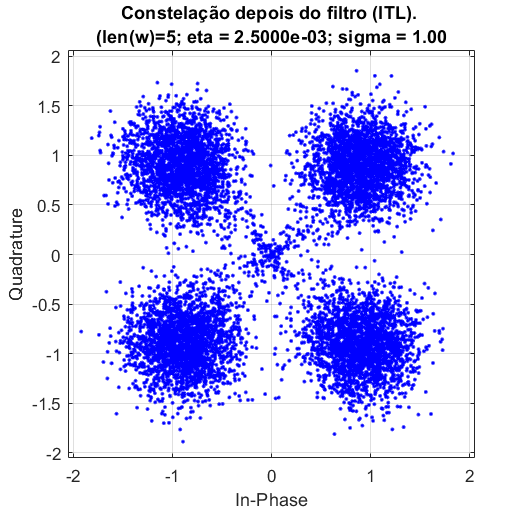

% Plota as constelações
% n_coef = n_coefs(iSER)
scatterplot(Y_SER);
name = sprintf("Constelação depois do filtro (ITL). \n(len(w)=%d; eta = %.4e; sigma = %.2f",...
                n_coefs(iSER), eta, sigma);
title(name); grid on;

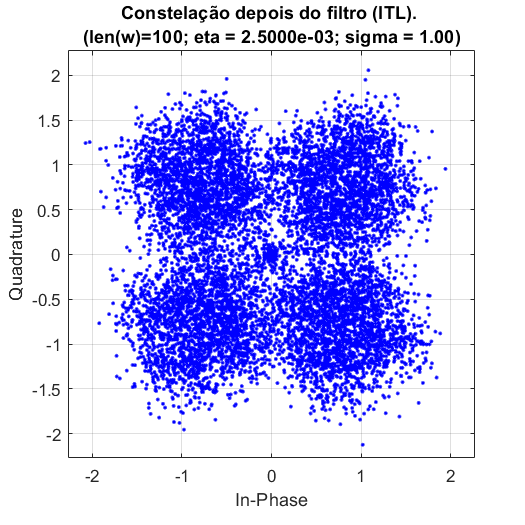


% n_coef = n_coefs(end)
scatterplot(Y_nMax);
name = sprintf("Constelação depois do filtro (ITL). \n(len(w)=%d; eta = %.4e; sigma = %.2f)", ...
                n_coefs(1),  eta, sigma);
title(name); grid on;

Podemos ver que como no caso do RLS o aumento no número de filtros ocasionou uma redução na perfomance do algoritmo no problema estudado.

De forma geral o RLS apresentou melhor desempenho do que o EEC com gradiente ascendente. O SER dos exemplos com RLS sempre foram inferiores do que os baseados em ITL, tal diferença pode ter sido ocasionada por:

- Mal ajuste dos hiper-parâmetros;

- A baixa complexidade do ga+EEC quando comparado ao RLS;

- A natureza gaussiana do ruído aditivo, sendo que o ITL teoricamente apresenta vantagens na presença de ruído não-gaussiano (ref livro sobre ITL, do Principe);

- Outra particularidade do problema beneficia o RLS sobre a técnica baseada em ITL utilizada.

## Funções locais:

function    [Y, w, e] = RLS(d, X, n_coef, lambda, delta)
    w = zeros(n_coef,1);
    n = length(d); m = n_coef;
    S = delta*eye(m);
    Y = zeros(n-m+1,1); % valor predito a priori
    e = zeros(n-m+1,1); % erro a priori
    for N=1:n-m+1
        x_in = X(N:N+m-1,1); % entrada do filtro
        Num = (lambda^-1)*S*x_in;
        Den = (1 + (lambda^-1) * x_in'*S*x_in);
        k = Num/Den;
        Y(N,1) = w'*x_in;
        e(N,1) = d(N,1) - Y(N,1);
        w = w + k*e(N,1)';
        S = (lambda^-1)*S - (lambda^-1)*k*x_in'*S;
    end
end


function [SER, BER, MME] = evalMetrics(d,Y,e,C)
    k = log2(C);
    dataSent_symbols     = qamdemod(d, C);
    dataReceived_symbols = qamdemod(Y, C);
    
    dataReceived_binary = de2bi(dataReceived_symbols, k);
    dataSent_binary     = de2bi(dataSent_symbols, k);
            
    % Taxa de erro de simbolos (Symbol Error Rate):
    SER=sum((dataReceived_symbols == dataSent_symbols(1:length(dataReceived_symbols))) == 0)/length(dataReceived_symbols);
        
    % Taxa de erro de bits (Bit Error Rate):
    BER=sum(sum(dataReceived_binary == dataSent_binary(1:length(dataReceived_binary),:) == 0))/numel(dataReceived_binary);
    
    % Média dos Módulos dos Erros
    MME = mean(abs(e));
end

function [Y, w, e] = gaEEC(d,X,n_coef,eta,sigma)
    w = zeros(n_coef,1); 
    n = length(d); m = n_coef;
    Y = zeros(n-m+1,1); % valor predito a priori
    e = zeros(n-m+1,1); % erro a priori
    for N=1:n-m+1
        x_in = X(N:N+m-1,1); % entrada do filtro
        Y(N,1) = w'*x_in;
        e(N,1) = d(N,1) - Y(N,1);
        deltaJ = 1/(sqrt(2*pi)*sigma^3) * exp(-e(N,1)^2/(2*sigma^2)) * e(N,1) * x_in';
        w = w + eta*deltaJ';
    end 
end